The first step is to load a model  and create a layout. For the purposes of this demo we will not be concerned with the metabolites used by the metabolic model, but this step is included because attempting to execute COMETS without any biomass will return a warning instead of completing the simulation.


load('Scerevisiae_iMM904.mat'); %Replace with any modellayout = createLayout(model);
layout = createLayout(iMM904);
layout = setInitialPop(layout,'1x1');


Add a simple extracellular reaction of the form A+B->C, with a reaction rate k = 0.2 s-1.


layout = addExternalReaction(layout,'reaction1',{'A' 'B' 'C'},...
    [-1 -1 1],'k',0.2);
layout = setMedia(layout,'A',1);
layout = setMedia(layout,'B',2);


Add an enzyme-catalyzed reaction of the form F->G, catalyzed by the enzyme E, with turnover rate 20 s-1 and KM 0.01 mmol.


layout = addExternalReaction(layout,'enz_reaction',{'S' 'P'},...
    [-1 1],'enzyme','E','kcat',2,'km',0.25);
layout = setMedia(layout,'S',1);
layout = setMedia(layout,'E',0.1);


Set a few parameters and execute the simulation.


layout.params.timeStep = 1/3600; %timestep = 1 second
layout.params.maxCycles = 25;
layout.params.writeMediaLog = 1;
runComets(layout)

Log file ./media.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\Users\ilija\Documents\GitHub\COMETS_Protocols\COMETS_protocols\COMETS_example_Extracellular_Reactions\Matlab


ans =     '
     C:\Users\ilija\Documents\GitHub\COMETS_Protocols\COMETS_protocols\COMETS_example_Extracellular_Reactions\Matlab>java -classpath "C:\Program Files\comets/lib/colt/lib/colt.jar";"C:\Program Files\comets/lib/colt/lib/concurrent.jar";"C:\Program Files\comets/lib/jdistlib-0.4.5-bin.jar";"C:\Program Files\comets/lib/commons-lang3-3.9/commons-lang3-3.9-sources.jar";"C:\Program Files\comets/lib/commons-lang3-3.9/commons-lang3-3.9.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-simple-1.0.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-sampling-1.0.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-jmh-1.0.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-core-1.0.jar";"C:\Program Files\comets/lib/commons-rng-1.0/commons-rng-client-api-1.0.jar";"C:\Program Files\comets/lib/commons-math3-3.6.1/commons-math3-3.6.1.jar";"C:\Program Files\comets/lib/commons-math3-3.6.1/commons-math3-3.6.1-tools.jar";"C:\Program Files\comets/lib/jun

Load the results and plot the data.

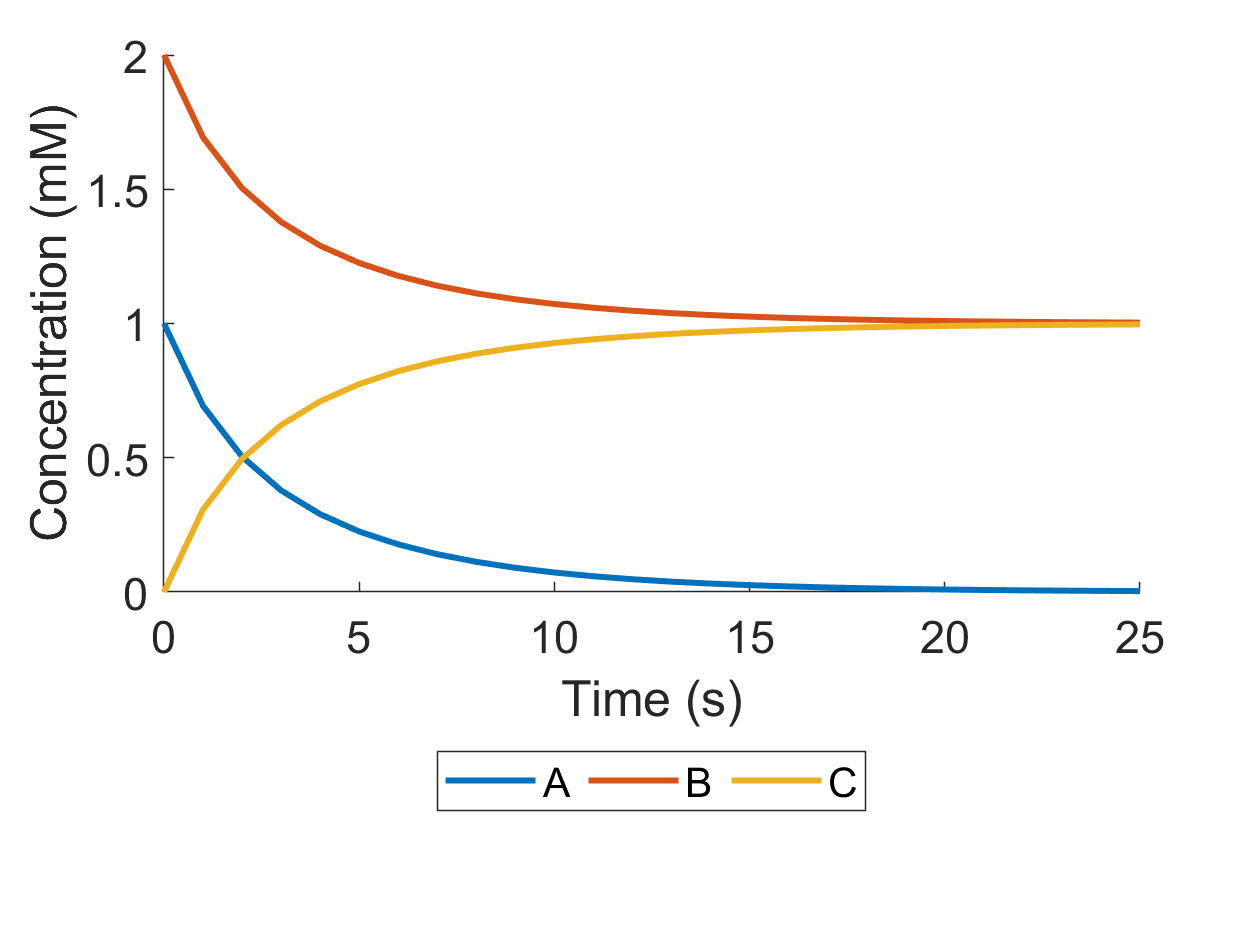


media = parseMediaLog(layout.params.mediaLogName,{'A' 'B' 'C' 'E' 'S' 'P'});
plotMediaTimecourse(media,{'A' 'B' 'C'});
%title('Binding Reaction (A + B → C)');
xlabel('Time (s)');
ylabel('Concentration (mM)');
set(gca,'FontName','Helvetica');
set(gca,'FontSize',15);
set(gca,'box','off');
overwritefiles = true;

if overwritefiles
    f = gca;
    saveas(f,'fig6A_notitle.fig');
    saveas(f,'fig6A_notitle.png');
    saveas(f,'fig6A_notitle.tif');
    saveas(f,'fig6A_notitle.pdf');
    saveas(f,'fig6A_notitle.eps');%for LaTeX
end

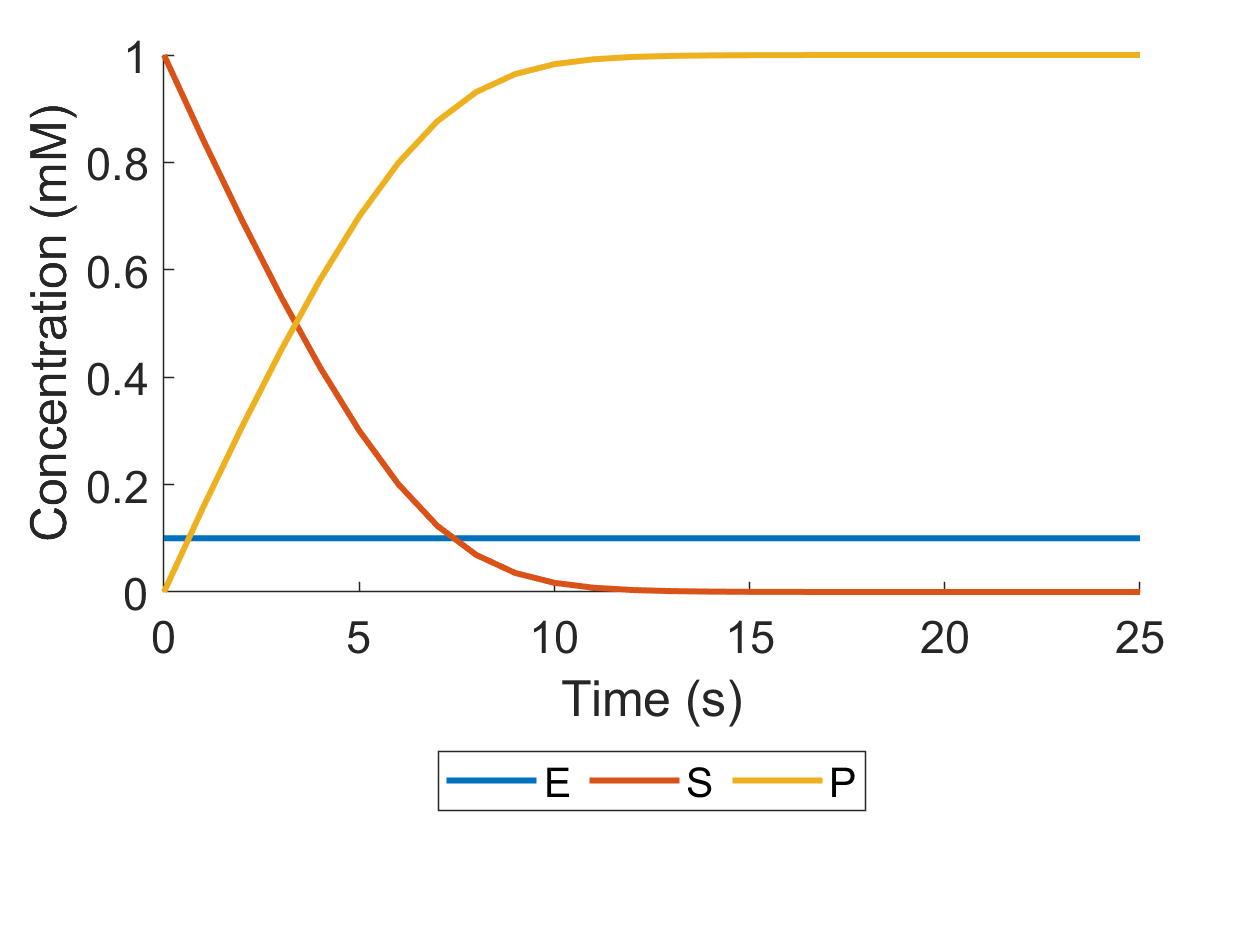


plotMediaTimecourse(media,{'E' 'S' 'P'});
%title('Enzyme Catalyzed Reaction (E + S → E + P)');
xlabel('Time (s)');
ylabel('Concentration (mM)');
set(gca,'FontName','Helvetica');
set(gca,'FontSize',15);
set(gca,'box','off');
overwritefiles = true;

if overwritefiles
    f = gca;
    saveas(f,'fig6B_notitle.fig');
    saveas(f,'fig6B_notitle.png');
    saveas(f,'fig6B_notitle.tif');
    saveas(f,'fig6B_notitle.pdf');
    saveas(f,'fig6B_notitle.eps');%for LaTeX
end